## Hydrological model. 

*Implement the hydrological model on the 6-year-long series of precipitation and discharge.*

clear 
close


%% Load data
load area_rating_curve.txt
load kc.txt % [-]
load P.txt % [mm/h]
load Q_obs.txt %[m^3/s]
load temperature.txt

Nyears=length(Q_obs)/(365*24);
day_month=[31 28 31 30 31 30 31 31 30 31 30 31]; %"day_month": number of days for each month
hour_month=day_month*24;
month_end=cumsum(day_month);                     %"month_end": last day of each month
month_start=month_end-day_month+1;               %"month_start": first day of each month
month_end_hour=cumsum(hour_month);                  
month_start_hour=month_end_hour-hour_month+1;

%%Parameters for the hydrological model
sw = 0.25;      %[-] Wilting point
s1 = 0.4;       %[-] Soil moisture stress threshold
n = 0.3;        %[-] Porosity
Q_b = 7;        %[m^3/s] Baseflow
t_sup = 22;     %[h] Mean superficial residence time
A = 4000;       %[km^2] Catchment area
phi = 38;       %[°] Latitude 

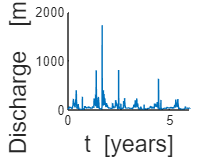

%% Plot discharge time series

figure(1)                                          %create a new figure
plot((1:length(Q_obs))/(365*24),Q_obs);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Discharge  [m^{3}/s]','FONTSIZE',14)       %insert label y axis
box off 

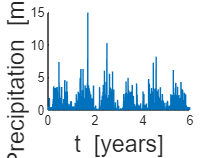

%% Plot precipitation time series

figure(2)                                          %create a new figure
plot((1:length(P))/(365*24),P);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Precipitation  [mm/h]','FONTSIZE',14)   %insert label y axis
box off

### 1.Compute reference crop evapotranspiration ET0 (potential evapotranspiration) through the Thornthwaite equation 

I = sum((temperature./5).^(1.514));
a = 6.75*(10^(-7))*(I^3) - 7.71*(10^(-5))*(I^2) + 1.79*(10^(-2))*I + 0.49; %experimental exponent
D = 1:365;
delt = 0.409*sin(2*pi*D/365-1.39);
w_s = acos(-tan(phi*pi/180)*tan(delt));
N_D = 24*w_s/pi; %number of daylight hours of day D
N_M =zeros(12,1); % mean daylight hours of month m


for i=1:12
    N_M(i) = sum((N_D(month_start(i):month_end(i))))/(day_month(i)); 
end

ET_0 = ((16.*(N_M/12).*(10*temperature/I).^a)/24)./day_month'; % [mm/h/unit area]


### 2. Attribute arbitrary values to the parameters K_sat, c, t_sub, z.

% Hydrological model: to be calibrated

K_sat = 1e-6*(3.6e6);      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5 [mm/h]
c = 10;              %[-] Exponent for power-law relation L(s)  1<c<20
z = 2000;              %[L] Root zone depth 1<z<2000 [mm]
t_sub = 200;          %[T] Mean sub-superficial residence time 1<t_sub<400
delta = [K_sat, c, z, t_sub];


% K_sat = 23.1423
% c = 16.4239
% z = 628.5144
% t_sub = 329.4774

### 3. Use an Euler explicit scheme to integrate the system of equations at hourly scale

% Settings
s = zeros(length(Q_obs),1);    % saturation vector
s(1) = 0.5;                    % initial arbitrary value

Vsup = zeros(length(Q_obs),1);  % superficial stored volume vector

Vsub = zeros(length(Q_obs),1);  % sub-superficial stored volume vector

N_hours_per_year = 365*24;  %number of hours per year
ET = zeros(length(Q_obs),1); 
L = zeros(length(Q_obs),1);

% Infiltration
K_sat_vect = ones(length(P),1)*K_sat;  % K_sat vector to compare with precipitation
I = min(P,K_sat_vect); %[mm/h]

% Runoff
R = P-I; %[mm/h]

for y=1:Nyears
    for m=1:12
        for h=month_start_hour(m):month_end_hour(m)
            t=(y-1)*N_hours_per_year+h; 
            if s(t)<=sw && s(t)>=0
                ET(t)= 0;
            elseif s(t)<=s1 && s(t)>sw
                ET(t)= kc(m)*ET_0(m)*((s(t)-sw)/(s1-sw));
            elseif s(t)<=1 && s(t)>s1
                ET(t)= kc(m)*ET_0(m);
            elseif s(t)>1
                    disp('Warning : s > 1')
            elseif s(t)<0
                    disp('Warning : s < 0')
            end
            L(t)=K_sat*(s(t)^c);
            s(t+1)=s(t)+((I(t)-ET(t)-L(t))*(1/(n*z)));
            Vsup(t+1)=Vsup(t)+R(t)-((t_sup^(-1))*Vsup(t));
            Vsub(t+1)=Vsub(t)+L(t)-((t_sub^(-1))*Vsub(t));
        end
    end
end


qsup=Vsup/t_sup;
qsub=Vsub/t_sub;
Qsup=A*qsup/3.6;
Qsub=A*qsub/3.6;

### 4. Test the mass balance of your system in order to ensure a correct implementation.

doTest=1;
dt=1;

%compute total discharge Q
if doTest % if doTest=1, check mass balance
    P_tot=sum(P)*dt;
    R_tot=sum(R)*dt;
    L_tot=sum(L)*dt;
    ET_tot=sum(ET)*dt;
    %"testS" balance for the root zone (input/output). testS = 1: necessary (but not sufficient)
    %condition for the implementation to be correct
    testS=P_tot/(ET_tot+R_tot+L_tot+n*z*(s(end)-s(1)))

    %"testQ" balance for the whole system (input/output). testQ = 1: necessary (but not sufficient)
    %condition for the implementation to be correct
    testQ=sum(P-ET)/(sum(qsup+qsub)+n*z*(s(end)-s(1))+Vsup(end)+Vsub(end))
end

testS = 1.0000

testQ = 1.0000

### 5. Evaluate the goodness of fit of the chosen parameter set by calculating the Nash-Sutcliffe index NS.

Q_mod = Qsub+Qsup+Q_b;
Q_mod = Q_mod(1:52560,1);
NS = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)))

NS = 0.4609



Q_mod = hydrological_model(P, Q_obs, ET_0, kc, delta(1),delta(2), delta(4), t_sup, delta(3), sw, s1, n, Q_b, A);
Q_mod = Q_mod(1:52560,1);
NS_old = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)))

NS_old = 0.4609

## Model calibration

Find the set of parameters {Ksat, c, tsub, z} that maximizes the Nash-Sutcliffe index. Use a simulated annealing strategy in order to find the parameter set that maximizes NS.

### 1. Define a functional form for the temperature

### 2. Attribute arbitrary values to the parameters Ksat, c, tsub, z. Run the hydrological model and evaluate NSold.

% K_sat = 1e-6*(3.6e6);      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5 
% c = 10;              %[-] Exponent for power-law relation L(s)  1<c<20
% z = 2000;              %[L] Root zone depth 1<z<2000 [mm]
% t_sub = 200;          %[T] Mean sub-superficial residence time 1<t_sub<400
% 
% delta = [K_sat, c, z, t_sub];

ranges = [0.99e-05*(3.6e6),19,1999,399];
upper_lim = [1e-5*(3.6e6),20,2000,400];
lower_lim = [1e-7*(3.6e6),1,1,1];
sigma = 5/100;
cr = 1/1200;

Q_mod = hydrological_model(P, Q_obs, ET_0, kc, delta(1),delta(2), delta(4), t_sup, delta(3), sw, s1, n, Q_b, A);
Q_mod = Q_mod(1:52560,1);
NS_old = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)))

NS_old = 0.4609

### 3. Select a new parameter set by drawing from a truncated normal distribution centered in the previous parameter set (use function TruncNormRnd.m)

delta_old=delta;
delta_new=delta;

Niter=1000;
niter = 1 ; 
while niter<Niter
    for i=1:length(delta)
        delta_new(i)=TruncNormRnd(delta_old(i),sigma*delta_old(i),lower_lim(i),upper_lim(i));
    end
    Q_mod = hydrological_model(P, Q_obs, ET_0, kc, delta_new(1),delta_new(2), delta_new(4), t_sup, delta_new(3), sw, s1, n, Q_b, A);
    Q_mod = Q_mod(1:52560,1);
    NS_new = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)))
    
    if NS_new>NS_old
        delta_old = delta_new;
        NS_old = NS_new;

    else
        r = rand;
        if r<exp((NS_new-NS_old)/t_sa(cr,niter))
            NS_old = NS_new;
        end
    end
    if NS_new >=0.85
        break
    end
    niter=niter+1;
end

NS_new = 0.3490

NS_new = 0.3632

NS_new = 0.3567

NS_new = 0.3580

NS_new = 0.3760

NS_new = 0.4017

NS_new = 0.3718

NS_new = 0.3940

NS_new = 0.4157

NS_new = 0.4120

NS_new = 0.3963

NS_new = 0.3779

NS_new = 0.4393

NS_new = 0.4446

NS_new = 0.4534

NS_new = 0.4791

NS_new = 0.4759

NS_new = 0.4966

NS_new = 0.5039

NS_new = 0.5166

NS_new = 0.5159

NS_new = 0.4835

NS_new = 0.5034

NS_new = 0.5391

NS_new = 0.5509

NS_new = 0.5604

NS_new = 0.5668

NS_new = 0.5794

NS_new = 0.5833

NS_new = 0.5738

NS_new = 0.5688

NS_new = 0.5834

NS_new = 0.5776

NS_new = 0.5748

NS_new = 0.5868

NS_new = 0.5875

NS_new = 0.5853

NS_new = 0.5785

NS_new = 0.5758

NS_new = 0.5766

NS_new = 0.5758

NS_new = 0.5624

NS_new = 0.5822

NS_new = 0.5776

NS_new = 0.5937

NS_new = 0.5999

NS_new = 0.6040

NS_new = 0.5995

NS_new = 0.5868

NS_new = 0.6027

NS_new = 0.5876

NS_new = 0.6098

NS_new = 0.6032

NS_new = 0.6008

NS_new = 0.6180

NS_new = 0.6096

NS_new = 0.6141

NS_new = 0.6231

NS_new = 0.6308

NS_new = 0.6320

NS_new = 0.5837

NS_new = 0.6324

NS_new = 0.6337

NS_new = 0.6216

NS_new = 0.6253

NS_new = 0.5623

NS_new = 0.6082

NS_new = 0.6169

NS_new = 0.6139

NS_new = 0.5712

NS_new = 0.6153

NS_new = 0.6349

NS_new = 0.6287

NS_new = 0.6479

NS_new = 0.6210

NS_new = 0.6543

NS_new = 0.6659

NS_new = 0.6737

NS_new = 0.6799

NS_new = 0.6693

NS_new = 0.6750

NS_new = 0.6621

NS_new = 0.6733

NS_new = 0.6717

NS_new = 0.6539

NS_new = 0.6734

NS_new = 0.6642

NS_new = 0.6682

NS_new = 0.6687

NS_new = 0.6459

NS_new = 0.6567

NS_new = 0.6402

NS_new = 0.6574

NS_new = 0.6517

NS_new = 0.6469

NS_new = 0.6900

NS_new = 0.6780

NS_new = 0.6938

NS_new = 0.6938

NS_new = 0.6928

NS_new = 0.6929

NS_new = 0.6796

NS_new = 0.6924

NS_new = 0.6812

NS_new = 0.6899

NS_new = 0.6981

NS_new = 0.6913

NS_new = 0.6955

NS_new = 0.6973

NS_new = 0.6968

NS_new = 0.6817

NS_new = 0.6880

NS_new = 0.6704

NS_new = 0.6815

NS_new = 0.6820

NS_new = 0.6693

NS_new = 0.6797

NS_new = 0.6703

NS_new = 0.6865

NS_new = 0.6865

NS_new = 0.6801

NS_new = 0.6922

NS_new = 0.6872

NS_new = 0.6916

NS_new = 0.6886

NS_new = 0.6898

NS_new = 0.6761

NS_new = 0.6833

NS_new = 0.6815

NS_new = 0.6729

NS_new = 0.6718

NS_new = 0.6951

NS_new = 0.6970

NS_new = 0.6898

NS_new = 0.6821

NS_new = 0.6941

NS_new = 0.6801

NS_new = 0.6989

NS_new = 0.6967

NS_new = 0.6931

NS_new = 0.7103

NS_new = 0.7013

NS_new = 0.7249

NS_new = 0.7257

NS_new = 0.7210

NS_new = 0.7229

NS_new = 0.7222

NS_new = 0.7204

NS_new = 0.7209

NS_new = 0.7219

NS_new = 0.7220

NS_new = 0.7237

NS_new = 0.7214

NS_new = 0.7264

NS_new = 0.7206

NS_new = 0.7254

NS_new = 0.7300

NS_new = 0.7253

NS_new = 0.7246

NS_new = 0.7314

NS_new = 0.7282

NS_new = 0.7250

NS_new = 0.7324

NS_new = 0.7351

NS_new = 0.7359

NS_new = 0.7358

NS_new = 0.7349

NS_new = 0.7312

NS_new = 0.7359

NS_new = 0.7366

NS_new = 0.7358

NS_new = 0.7365

NS_new = 0.7366

NS_new = 0.7360

NS_new = 0.7361

NS_new = 0.7332

NS_new = 0.7348

NS_new = 0.7360

NS_new = 0.7334

NS_new = 0.7375

NS_new = 0.7352

NS_new = 0.7340

NS_new = 0.7373

NS_new = 0.7362

NS_new = 0.7352

NS_new = 0.7379

NS_new = 0.7371

NS_new = 0.7372

NS_new = 0.7363

NS_new = 0.7349

NS_new = 0.7369

NS_new = 0.7371

NS_new = 0.7373

NS_new = 0.7366

NS_new = 0.7388

Index exceeds the number of array elements. Index must not exceed 14720.

Error in hydrological_model (line 57)
                s(t+1)=s(t)+((I(t)-ET(t)-L(t))*(1/(n*z)));